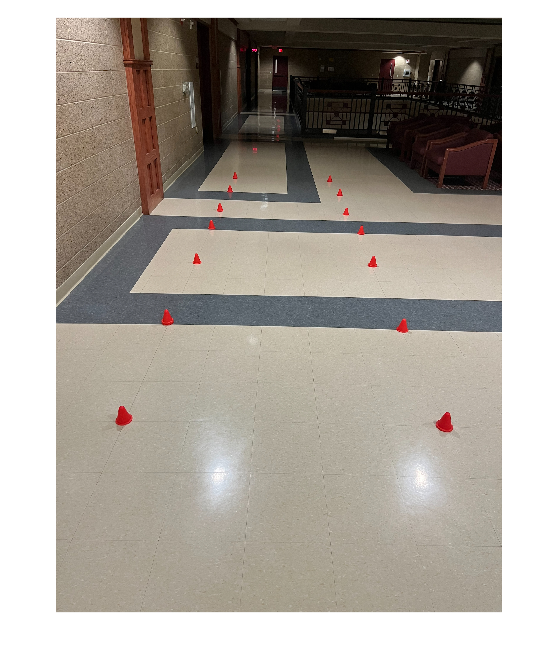

%Author: Shufan Sun
%date: 2023-12-19

data = imread('red.png');%read the image from the folder
imshow(data,[])%show the image

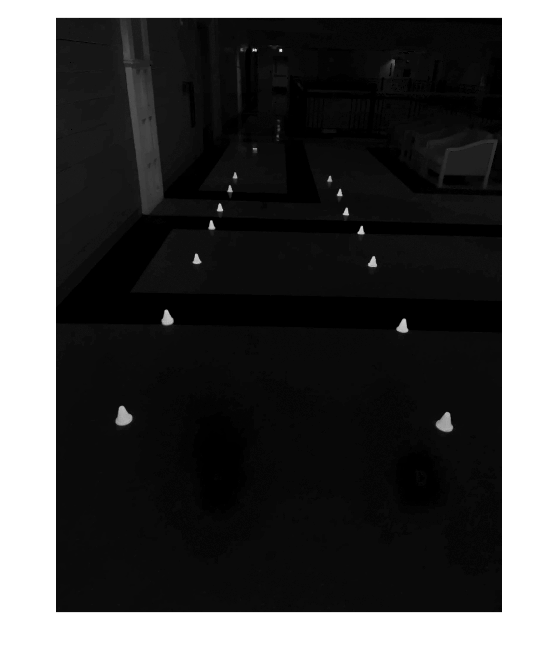


diff_im=imsubtract(data(:,:,1),rgb2gray(data));
 %extracting the Red color from grayscale image
imshow(diff_im,[])%show the image

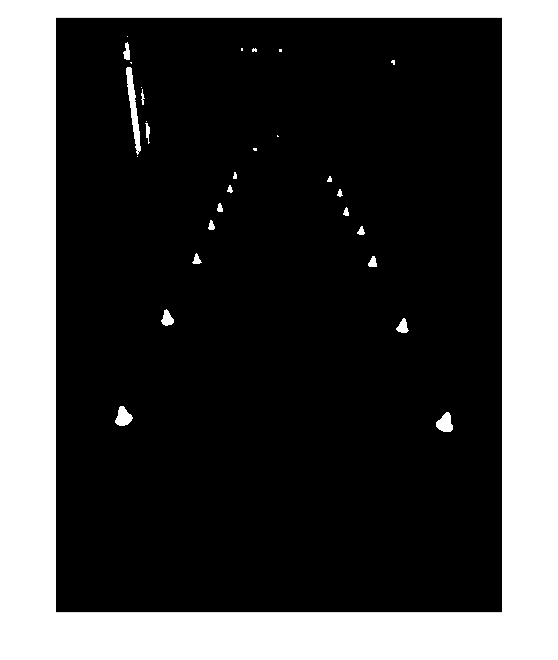


diff_im=imbinarize(diff_im,0.18);
imshow(diff_im,[]);

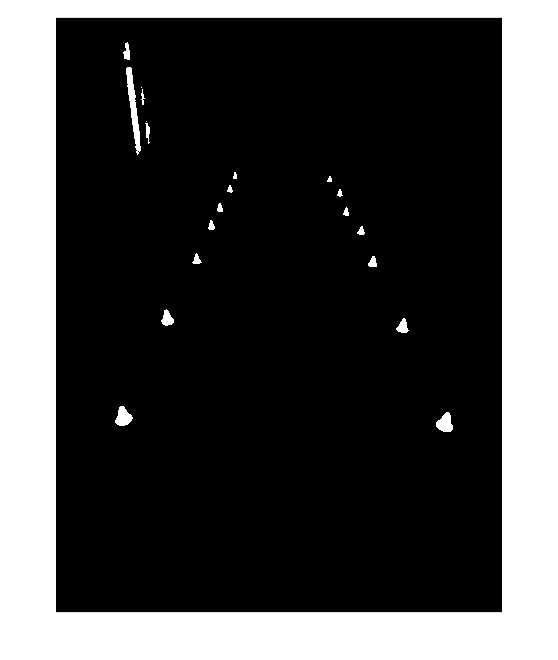

 %Converting grayscale image into binary image

  diff_im=bwareaopen(diff_im,300);
  %remove all pixels less than 300 pixel
  imshow(diff_im,[])%show the image

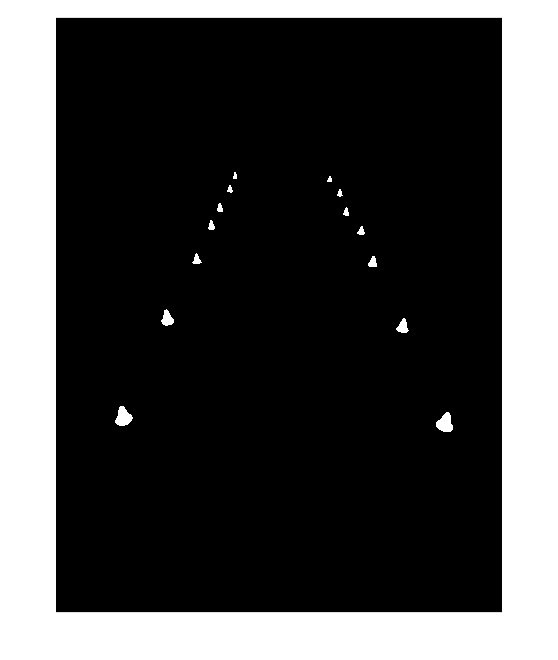


 diff_im(100:600, 100:600) = 0;
%  remove the red door that disrupts drawing the lines for cones
  imshow(diff_im,[])%show the image


 filled_img=imfill(diff_im,"holes")

filled_img = 2420×1816 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

 %fill the little holes with color
 imshow(filled_img)


%  label the image
 labeled_img=bwlabel(filled_img)

labeled_img =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

% try to find the left most end of the left part of the path
stats = regionprops(labeled_img, 'Area', 'Centroid', 'BoundingBox');
left_end = [];
for i = 1:numel(stats)
    %try to find an area of whiteness that's labeled 1 in the grid
    if stats(i).Area > 100 && stats(i).BoundingBox(1) < size(diff_im, 2)/2
        %when the area is big enough, it means that we have a cone that's
        %at this area
        left_end = stats(i);
        break;
    end
end

figure;
imshow(diff_im);
hold on;
rectangle('Position', left_end.BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);


% find the right most end of the right path
stats = regionprops(labeled_img, 'Area', 'Centroid', 'BoundingBox');
right_end = [];
for i = numel(stats):-1:1
    if stats(i).Area > 100 && stats(i).BoundingBox(1) + stats(i).BoundingBox(3) > size(diff_im, 2)/2
        right_end = stats(i);
        break;
    end
end
rectangle('Position', right_end.BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);

% find the leftmost point of the right path
stats = regionprops(labeled_img, 'Area', 'Centroid', 'BoundingBox');
right_start = [];
for i = 1:numel(stats)
    if stats(i).Area > 100 && stats(i).BoundingBox(1) + stats(i).BoundingBox(3) > size(diff_im, 2)/2
        right_start = stats(i);
        break;
    end
end

rectangle('Position', right_start.BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);

% find the rightmost point of the left path
stats = regionprops(labeled_img, 'Area', 'Centroid', 'BoundingBox');
left_start = [];
for i = numel(stats):-1:1
    if stats(i).Area > 100 && stats(i).BoundingBox(1) < size(diff_im, 2)/2
        left_start = stats(i);
        break;
    end
end

rectangle('Position', left_start.BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);
imshow(data)

left_centroid=left_start.Centroid

left_centroid =   729.8589  645.6121


left_centroid2=left_end.Centroid

left_centroid2 = 1.0e+03 *

    0.2754    1.6264


% Connect left_start to left_end with a red line
x = [left_centroid(1) left_centroid2(1)];
y = [left_centroid(2) left_centroid2(2)];
line(x, y, 'Color', 'red');

right_centroid=right_start.Centroid

right_centroid = 1.0e+03 *

    1.1154    0.6590


right_centroid2=right_end.Centroid

right_centroid2 = 1.0e+03 *

    1.5849    1.6524


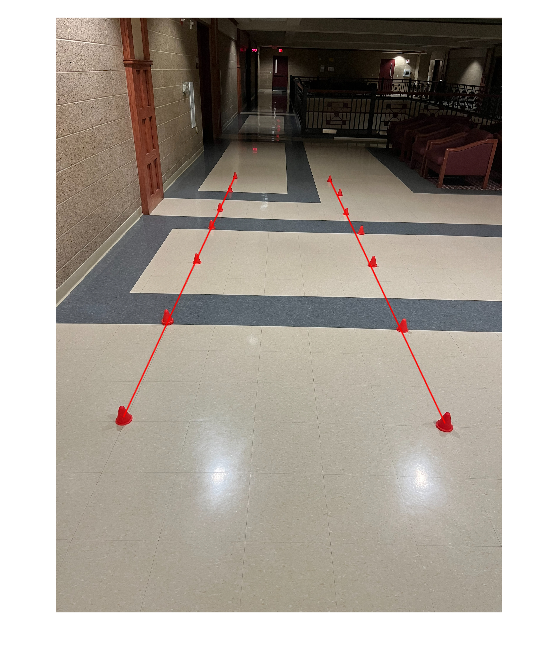

% Connect right_start to right_end with a red line
x = [right_centroid(1) right_centroid2(1)];
y = [right_centroid(2) right_centroid2(2)];
line(x, y, 'Color', 'red');